# **Introductory script illustrating how to compute treeshrew cone mosaic excitation responses to an ISETBio scene from a JPEG scene.**

*This tutorial generates an ISETBio scene from a JPEG file as realized on a particular display, passes this scene through the default  treeshrew optics, and computes cone mosaic excitation responses. The simulation parameters here are appropriate for treeshrew experiments.*

**See also**: 

- `t_sceneForStimulusOnDisplay.mlx`  (more info on scene generation)

- `t_coneIsomerizationsFromSceneOnDisplay.mlx ` (parameters specific to the human visual system)

- t_opticsTreeShrew.mlx (expore various optics params)

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2018*

# **Step 1.** Create a presentation display and a low-frequency Gabor stimulus realized on that display

We employ an existing display specification, here an Apple LCD display and some typical params for a Gabor stimulus.

%% Create presentation display and place it 5 cm in front of the eye
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 5/100);

%% Load the eagle.jpg image and realized it on the presentation display
meanLuminanceCdPerM2 = 40;
fileName = fullfile(isetbioDataPath, 'images', 'rgb', 'eagle.jpg');
realizedStimulusScene = sceneFromFile(fileName, 'rgb', ...
    meanLuminanceCdPerM2, presentationDisplay);

[vcReadImage] Assuming an 8bit image and a 10 bit LUT


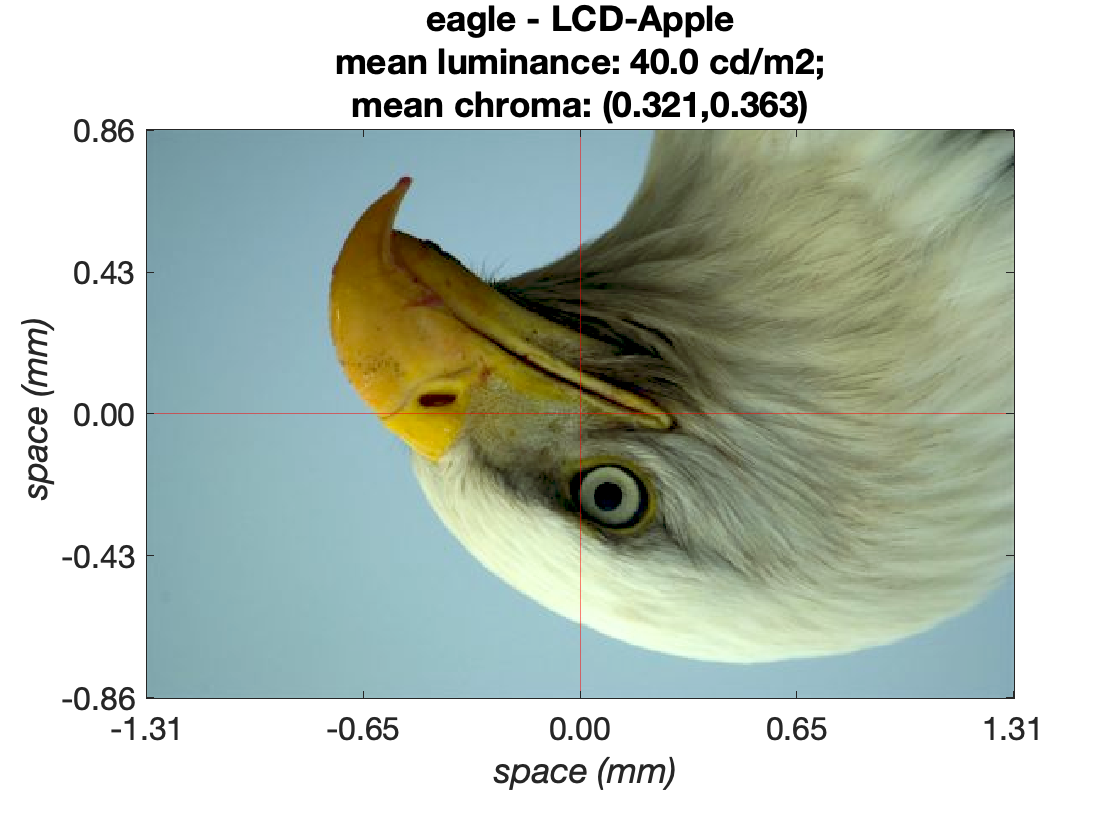

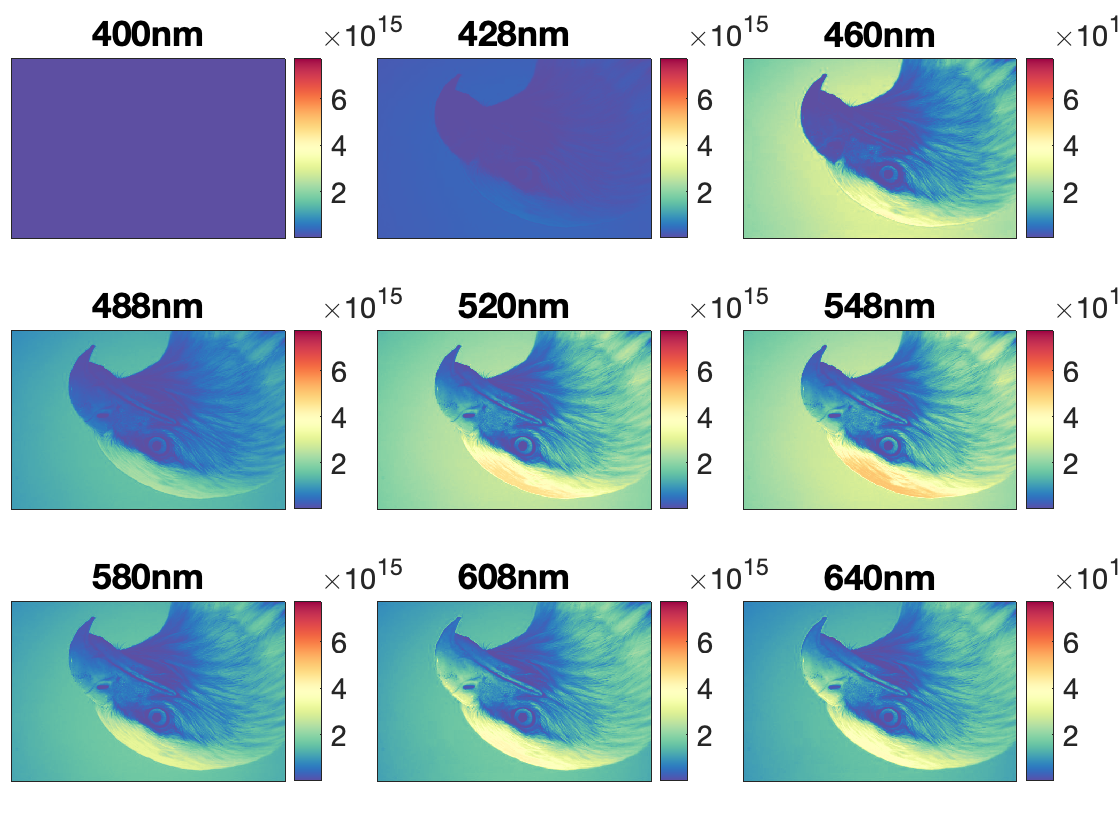

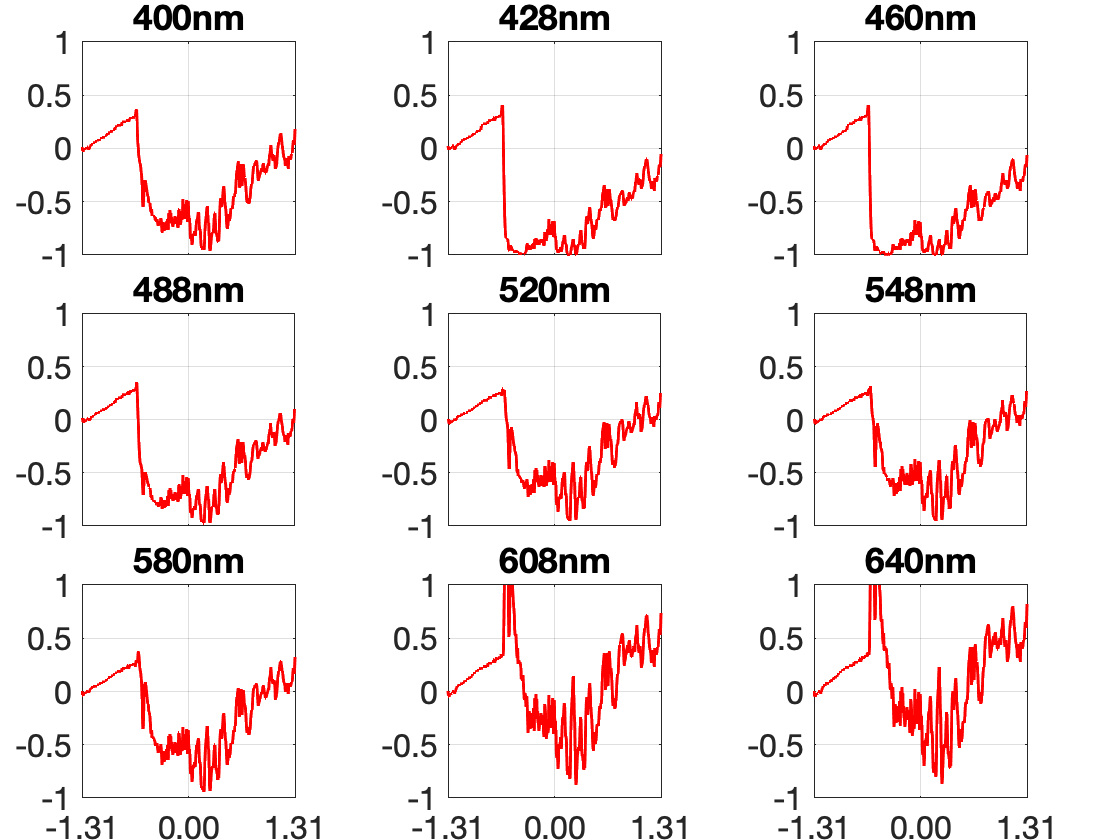


% Set a 4 deg FOV
sceneFOVdegs = 3.0;
realizedStimulusScene = sceneSet(realizedStimulusScene, 'fov', sceneFOVdegs);

% Visualize different aspects of the generated scene
visualizeScene(realizedStimulusScene, 'displayContrastProfiles', true);

# **Step 2.** Compute the optical image using the default TreeShrew optics

We employ the default treeshrew optics which are based on a Gaussian PSF. The scene is passed through the optics model to compute the retinal image.

%% Generate default treeshrew optics
theOI = oiTreeShrewCreate();

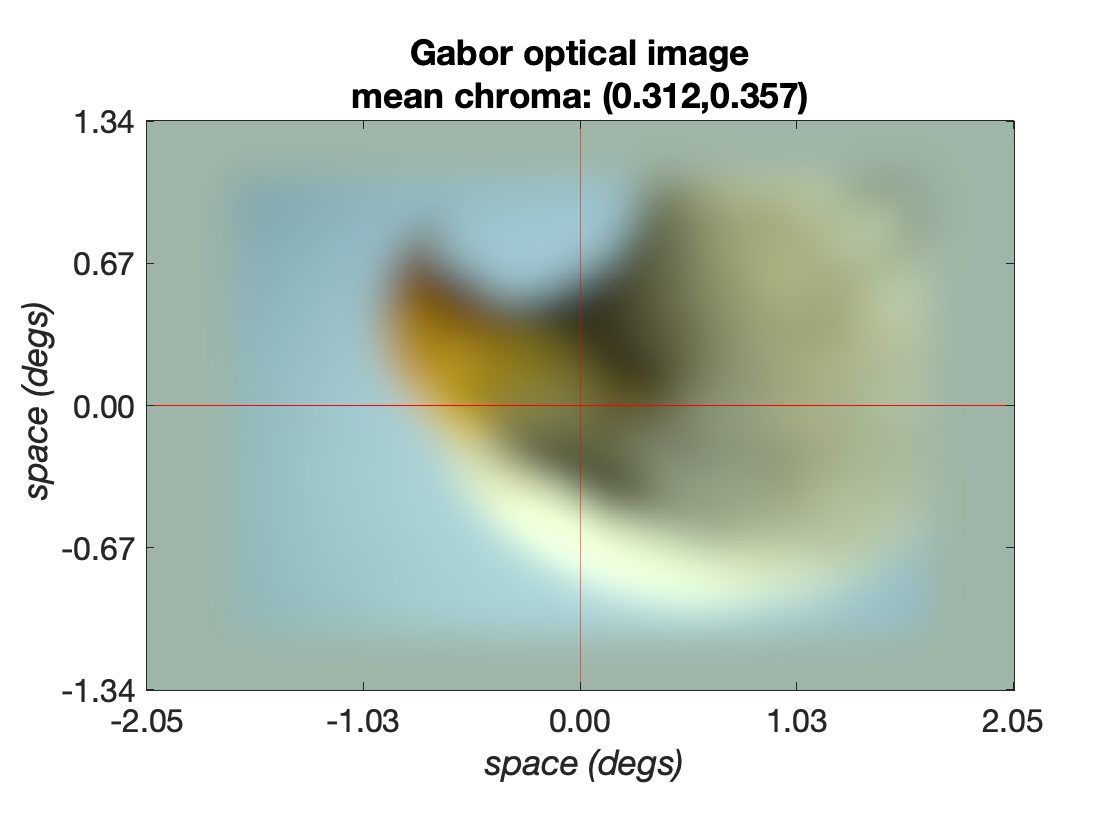

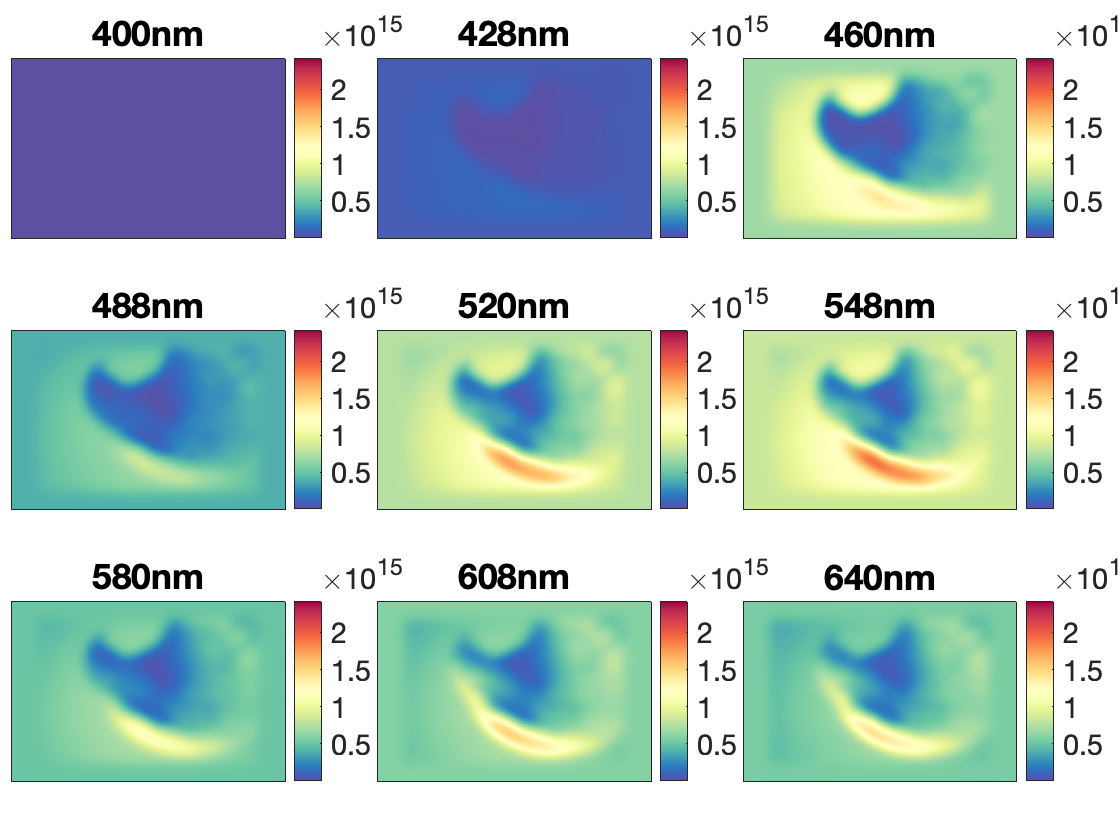

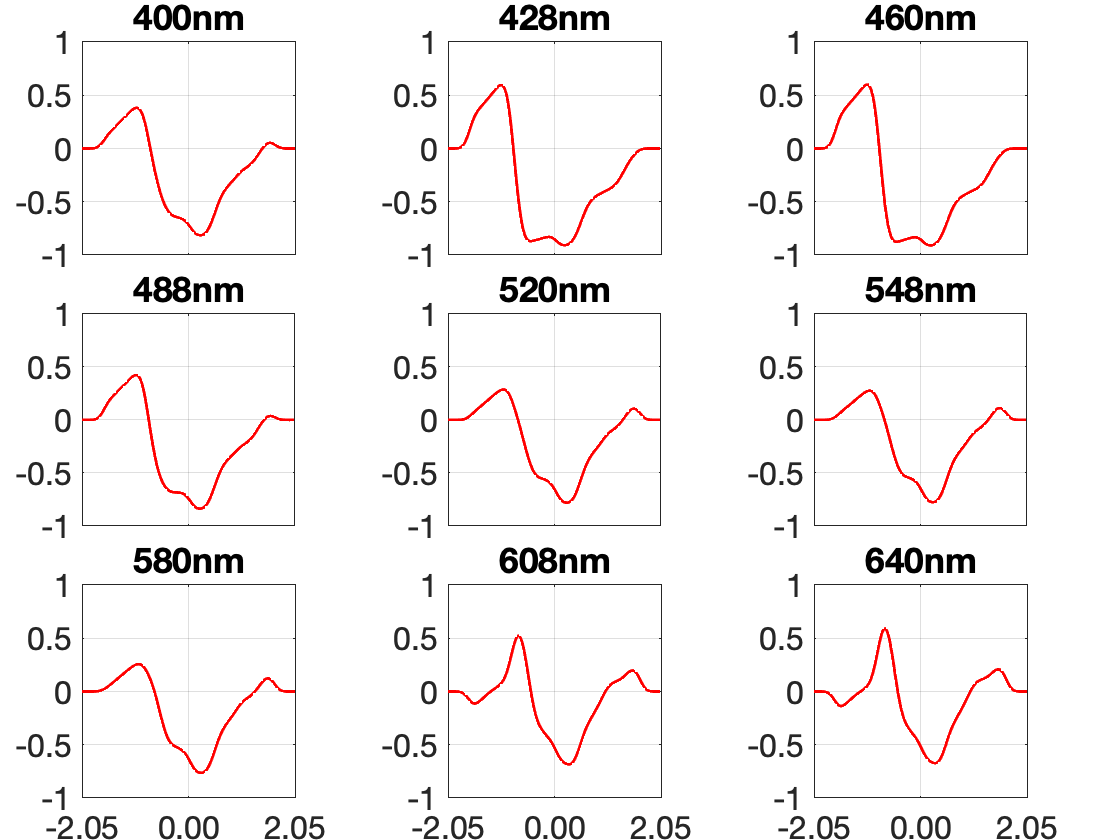


%% Compute the retinal image
theOI = oiCompute(theOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theOI, 'displayRetinalContrastProfiles', true);

# **Step 3.** Generate the default TreeShrew cone mosaic

Generate and visualize the default three shrew cone mosaic

% Generate default treeshrew cone mosaic with a 5 msec integration time
theConeMosaic = coneMosaicTreeShrewCreate(...
    theOI.optics.micronsPerDegree, ...
    'fovDegs', 1.5*sceneFOVdegs*[1 1], ...
    'integrationTime', 1/1000);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 1134
Scones after making an S-cone free central patch: 1134 (added Lcones:0, added Mcones:0)
Scones after pass 1: 662 (added Lcones:608, added Mcones:0)
Scones after pass 2: 387 (added Lcones:362, added Mcones:0)
Scones after pass 3: 239 (added Lcones:190, added Mcones:0)
Scones after pass 4: 194 (added Lcones:52, added Mcones:0)
Scones after pass 5: 187 (added Lcones:7, added Mcones:0)
Scones after pass 6: 185 (added Lcones:2, added Mcones:0)
Scones after pass 7: 185 (added Lcones:0, added Mcones:0)


theConeMosaic.displayInfo();


Mosaic info:
                                      Size (microns): 338.0 (w) x 338.0 (h)
                                           FOV (deg): 4.45 (w) x 4.45 (h)
                                   Retinal coverages: 0.783 (aperture) x 0.898 (geometric)
                              Grid resampling factor: 7
                   Inner segment diameter (microns):  Min=1.5797, Mean=3.8397, Median=3.9689, Max=5.1036 
                     Inner segment area (microns^2):  Min=1.9600, Mean=11.5795, Median=12.3714, Max=20.4567 
                     Cone geometric area (microns^2): 44.1786 
               Cone light colleting area (microns^2): 38.4845
                                    Rectangular grid: 43 cols x 43 rows
                                      Resampled grid: 1183 cols x 1183 rows
                                         Total cones: 1399489
                                        Active cones: 2269
                                            L- cones: 2084 (0.918%)
            

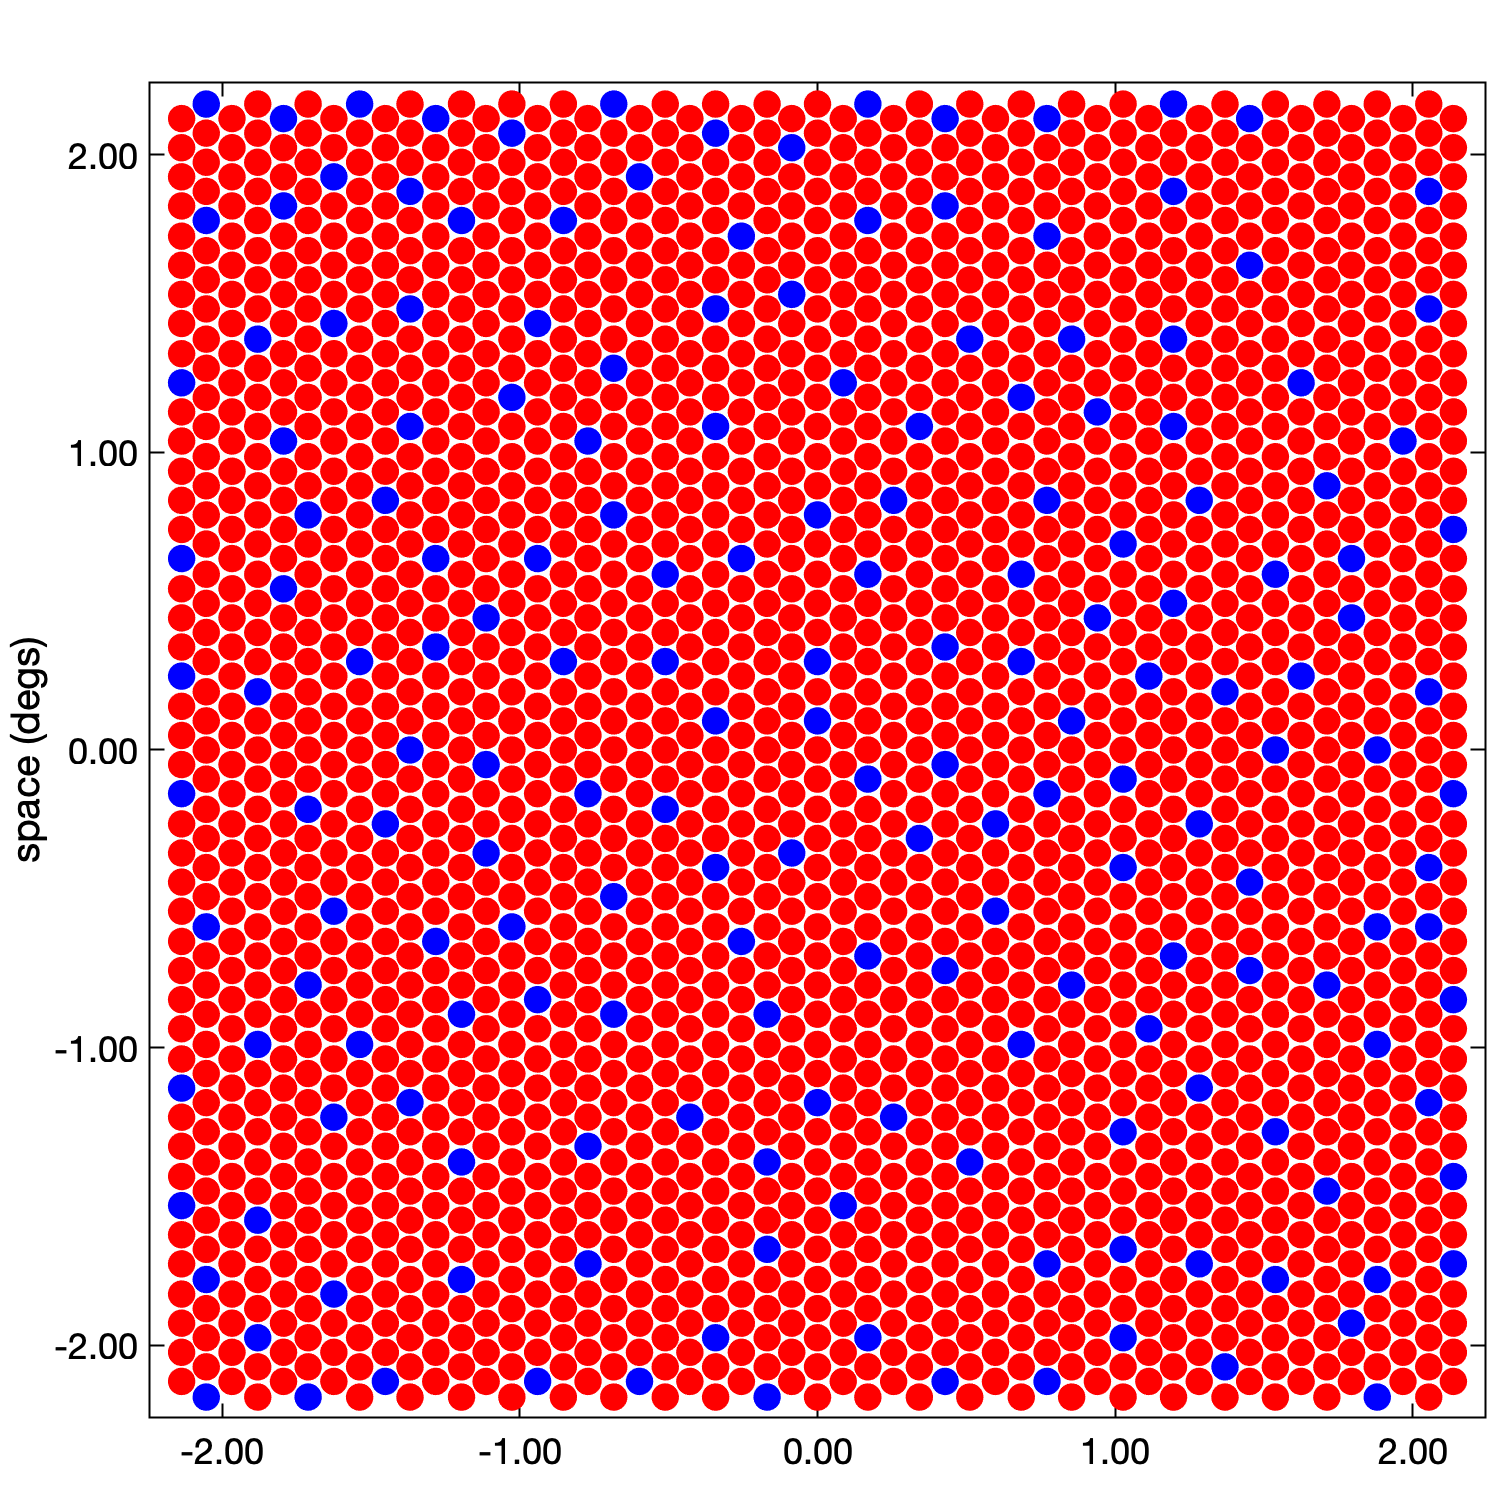

theConeMosaic.visualizeGrid('backgroundColor', [1 1 1], ...
    'generateNewFigure', true, 'displayVisualDegs', true); 

# **Step 4.** Generate cone excitation responses to the optical image

### Step 4.1 Generate responses

Here we are generating some cone excitation response instances

nTrialsNum = 3;
emPath = zeros(nTrialsNum, 1, 2);
% Compute mosaic excitation responses
coneExcitations = theConeMosaic.compute(theOI, 'emPath', emPath);

### Step 4.2 Visualize results. 

We are visualizing the cone mosaic on the left, along with the first two response instances. All computed responses instances for cones located along the horizontal meridian are visualized on the bottom plot.

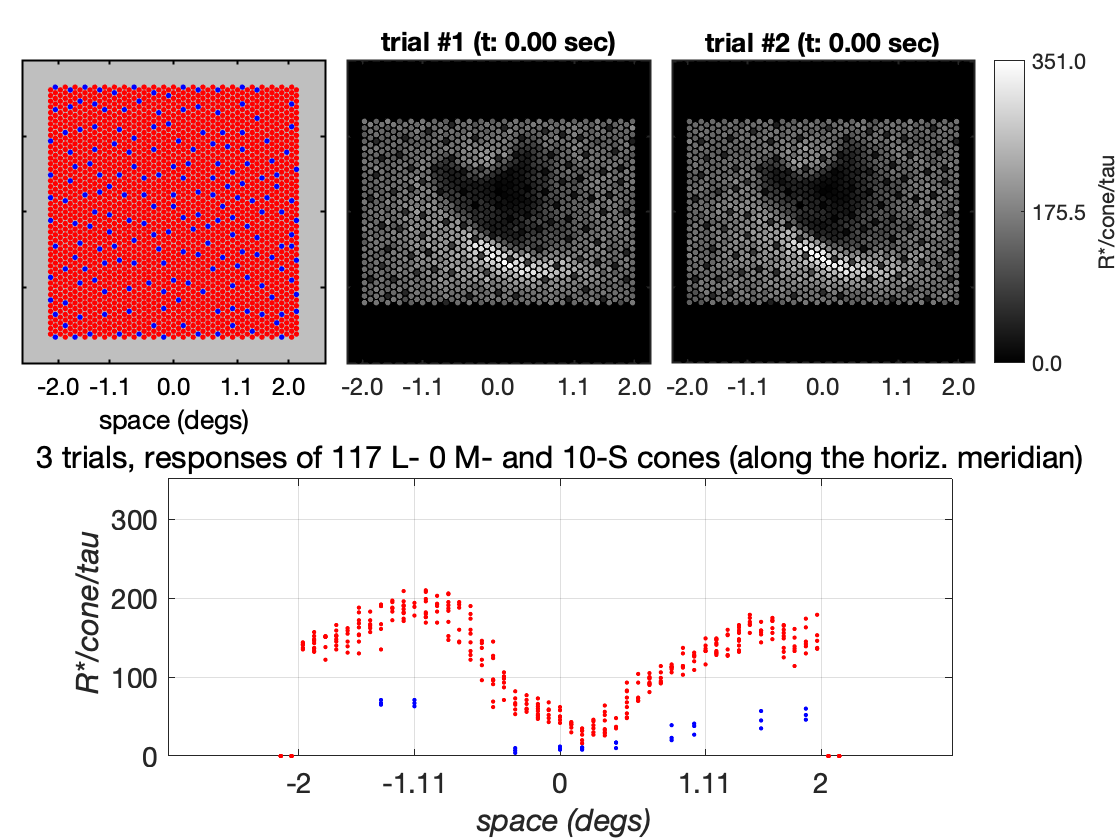

%% Visualize cone mosaic and its cone excitation responses
visualizeConeMosaicResponses(theConeMosaic, coneExcitations, 'R*/cone/tau');

### Step 4.3 Demosaic cone responses

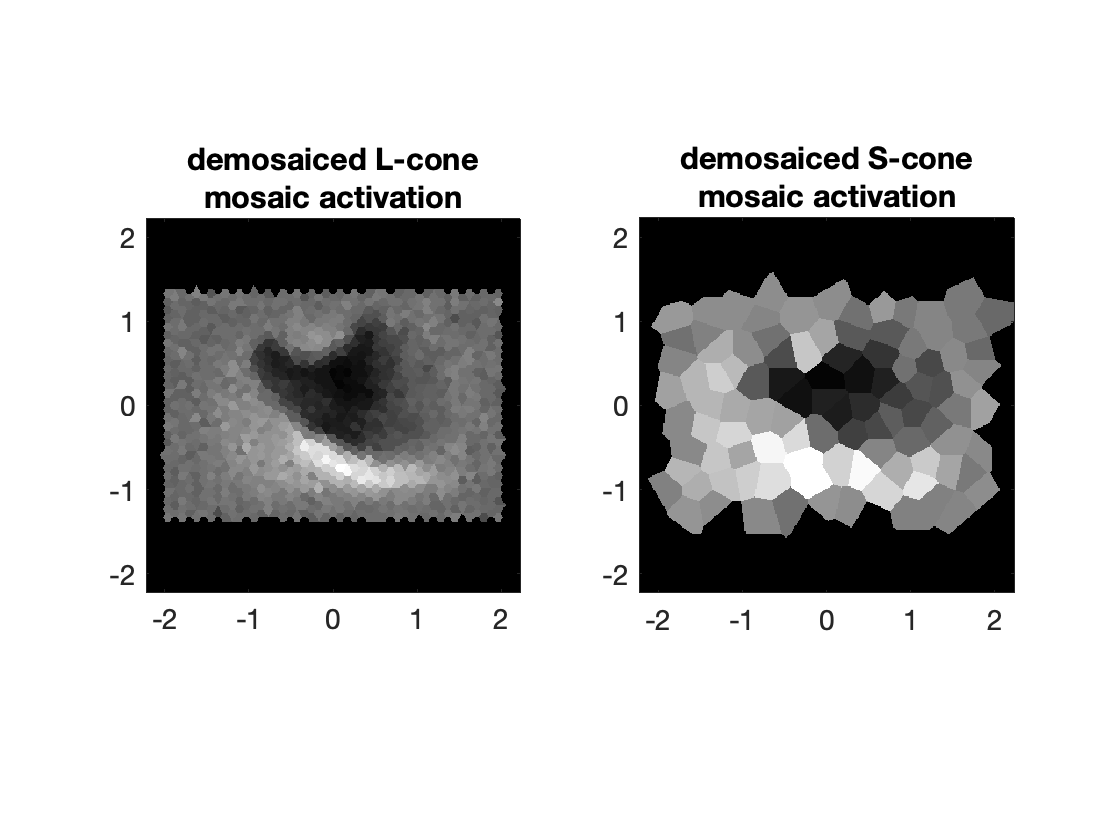

trialNo = 1;
coneExcitationsRates = squeeze(coneExcitations(trialNo,:,:))/ theConeMosaic.integrationTime;

demosaicingSampleSpacingMicrons = 1;

[theDemosaicedLconeIsomerizationMap, demosaicedMapSupportDegs, ...
 theLConeIsomerizations, lConeXlocsDegs, lConeYlocsDegs] = ...
 theConeMosaic.demosaicConeTypeActivationFromFullActivation('L-cones', ...
 coneExcitationsRates, demosaicingSampleSpacingMicrons);

[theDemosaicedSconeIsomerizationMap, demosaicedMapSupportDegs, ...
 theLConeIsomerizations, sConeXlocsDegs, sConeYlocsDegs] = ...
 theConeMosaic.demosaicConeTypeActivationFromFullActivation('S-cones', ...
 coneExcitationsRates, demosaicingSampleSpacingMicrons);

% Visualize demosaiced response
figure();clf;
subplot(1,2,1)
imagesc(demosaicedMapSupportDegs, demosaicedMapSupportDegs, theDemosaicedLconeIsomerizationMap);
axis 'image'; axis 'xy'
title(sprintf('demosaiced L-cone\nmosaic activation'))
set(gca, 'FontSize', 14, 'XTick', [-10:1:10], 'YTick', [-10:1:10])
subplot(1,2,2);
imagesc(demosaicedMapSupportDegs, demosaicedMapSupportDegs, theDemosaicedSconeIsomerizationMap);
axis 'image'; axis 'xy'
title(sprintf('demosaiced S-cone\nmosaic activation'))
set(gca, 'FontSize', 14, 'XTick', [-10:1:10], 'YTick', [-10:1:10])
colormap(gray)